warning off
init_unfold


Adding toolboxes and subfolders to path... 


warning on

# Introduction

This basic tutorial starts with generating some EEG data with overlap. For the sake of having a backstory, we will simulate data of an experiment where we have two types of stimuli (face or car) with two types of colors (red and green) embedded in pink noise. Subjects are asked to count the number of objects irregardless of color.

We are interested what the influences of the stimulus-type and color is.

This tutorial only shows the minimally necessary functions. Have a look at the second tutorial for more extensive explanations and plotting functions.

% We will first simulate data based on the car/face, green/red design.
EEG = tutorial_simulate_data('2x2')

eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


# Defining the 2x2 factorial design

A 2x2 anova is equal to a linear model with two categorical predictors and the interaction. We adopt the widely popular 'formula'-style of model definition. In this case 'y ~ A + B + A:B' (equivalent: 'y ~ A*B') represents the whole model. A and B are our main effects, A:B the interaction. We should specify that we have two categorical factors and we have to specify on which event(s) we want to epoch our data and evaluate the model.

cfgDesign = [];
cfgDesign.eventtype = {'fixation'};
cfgDesign.formula = 'y ~ 1+ cat(stimulusType)*cat(color)'

cfgDesign =     eventtype: {'fixation'}
      formula: 'y ~ 1+ cat(stimulusType)*cat(color)'


EEG = dc_designmat(EEG,cfgDesign);

Modeling event(s) [fixation] using formula: y ~ 1+ cat(stimulusType)*cat(color) 



removeList =

     []



# Timeshift

In order to compensate for the inevitable linear overlap between ERPs, we want to use timeshifting / prepare the designmatrix for the deconvolution step. In this step we generate for each column of the designmatrix timeshifted (by t = 1, t=2, t=3 ...) and append them to the designmatrix.

cfgTimeexpand = [];
cfgTimeexpand.timelimits = [-.3,1.5];

EEG = dc_timeexpandDesignmat(EEG,cfgTimeexpand);


dc_timeexpandDesignmat(): Timeexpanding the designmatrix...
...done


# Fit the model

We solve the linear equation: $y=\beta X$ (y=data, X= Designmatrix) for $\beta$ at each point in time. These betas reflect our parameter estimates.

EEG= dc_glmfit(EEG);


dc_glmfit(): Fitting deconvolution model...solving the equation system

solving electrode 1 (of 1 electrodes in total)... 35 iterations, took 0.6s
 LMfit finished 


# Plot the results

We choose a single electrode and plot all effects.

Evaluating parameters at auto or specified values

plotting all parameters


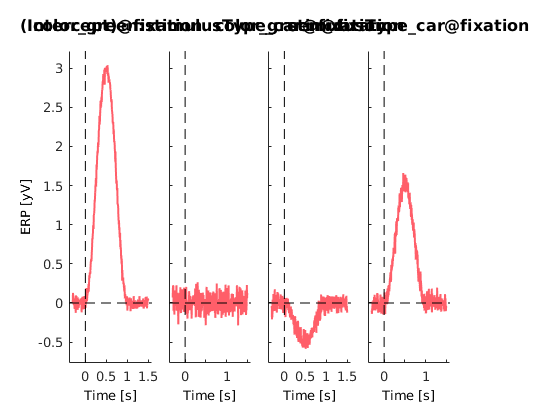

unfold= dc_beta2unfold(EEG);

cfg = [];
cfg.channel = 1;
ax = dc_plotParam(unfold,cfg);

One can clearly see that we recover the intercept and the simulated effects. The intercept represents the response when both stimulusType = 'face' and color = 'red'. The second column is the component one needs to add to the intercept to gain the ERP for the color 'green'. The third column equally represents the difference (i.e. what to add) of car to face. The second column represents the interaction. Because we did not simulate an interaction, this field is basically flat.